## Initialise

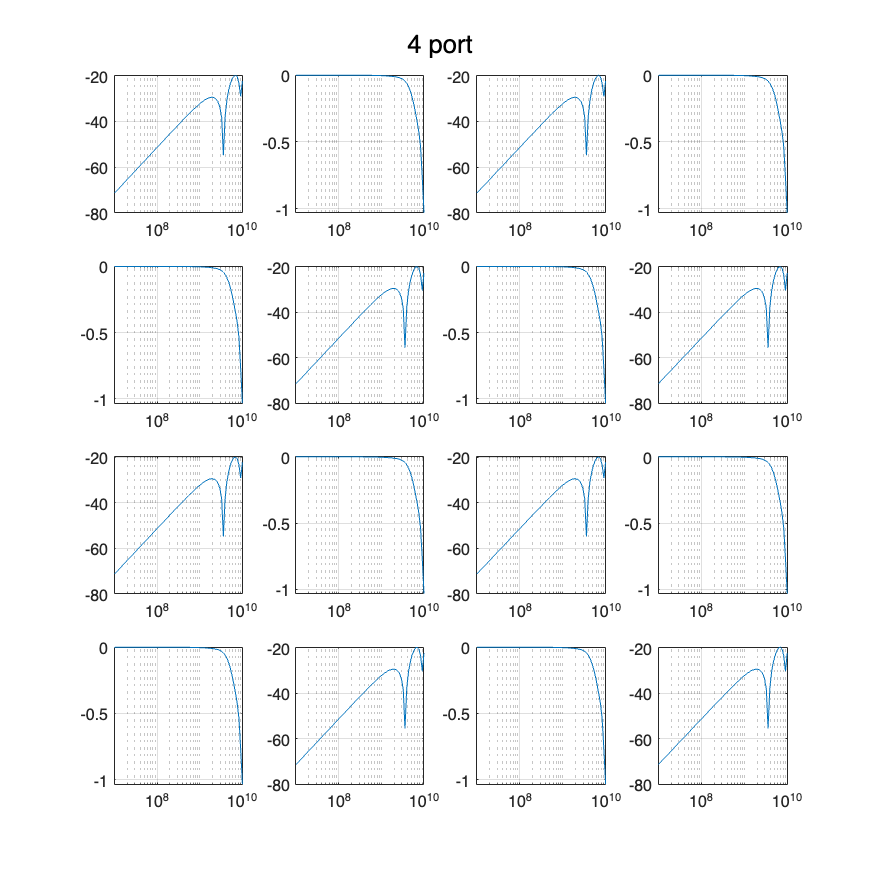

% Define the coupled microstrip line
mline = microstripLine;

% Generate S-parameters
fpoints = 500;
f = linspace(1e9, 0.5e11, fpoints);
spar = sparameters(mline, f, 50);

num_of_sections = 8; l = 4e-6;

% Extract S-parameter data
S = spar.Parameters;

S = cat(1, cat(2, S, S), cat(2, S, S));

plot_full_S_params(f, S, '4 port');

## Odd and Even Mode S parameters

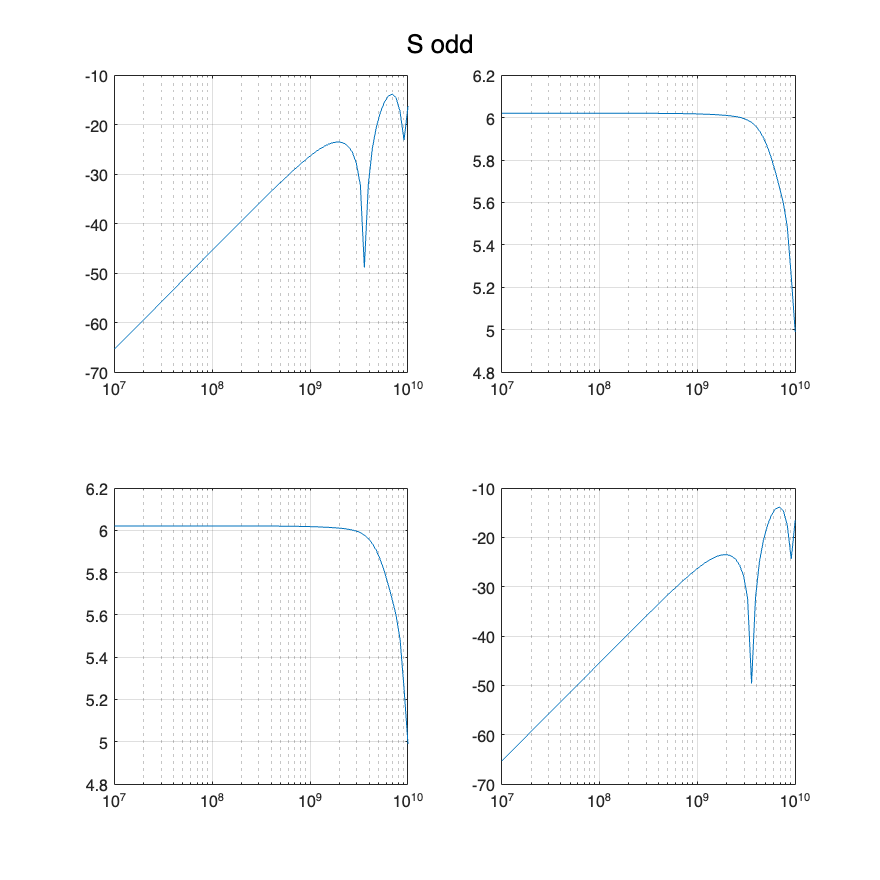

% Initialize matrices for SA and SB
SA = zeros(2, 2, fpoints);
SB = zeros(2, 2, fpoints);

% Extract SA and SB from sparam_array
for k = 1:fpoints
    SA(:, :, k) = S(1:2, 1:2, k);
    SB(:, :, k) = S(1:2, 3:4, k);
end

S_odd = SA + SB;
S_even = SA - SB;

plot_S_params(f, S_odd, 'S odd');

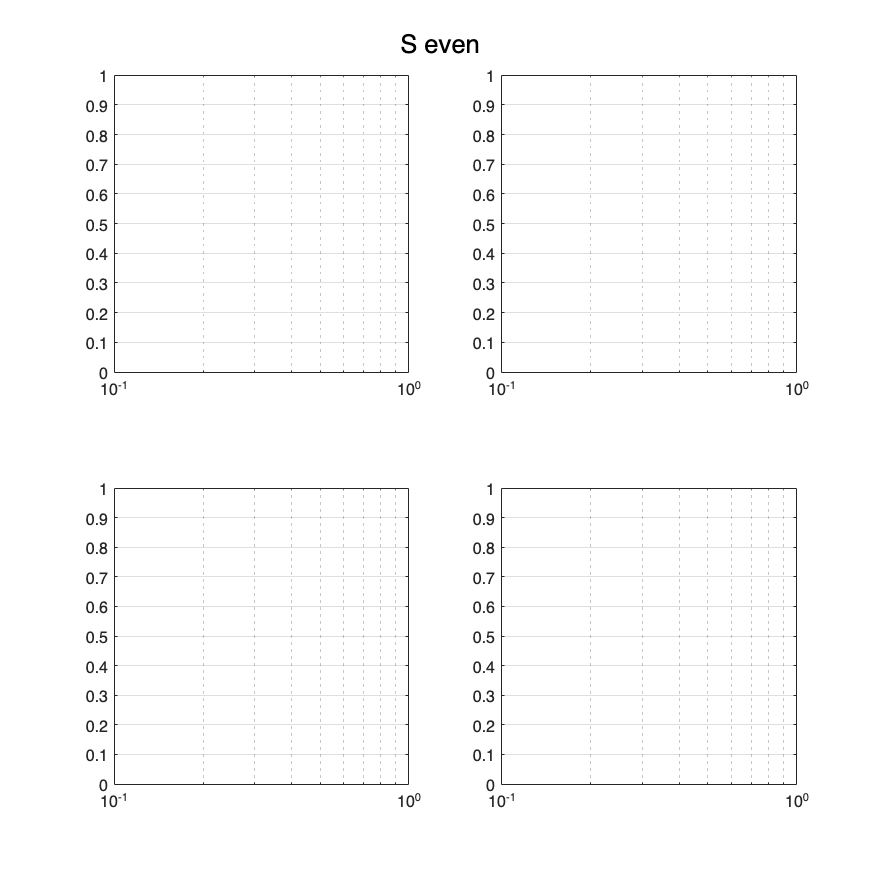

plot_S_params(f, S_even, 'S even');

## S to ABCD

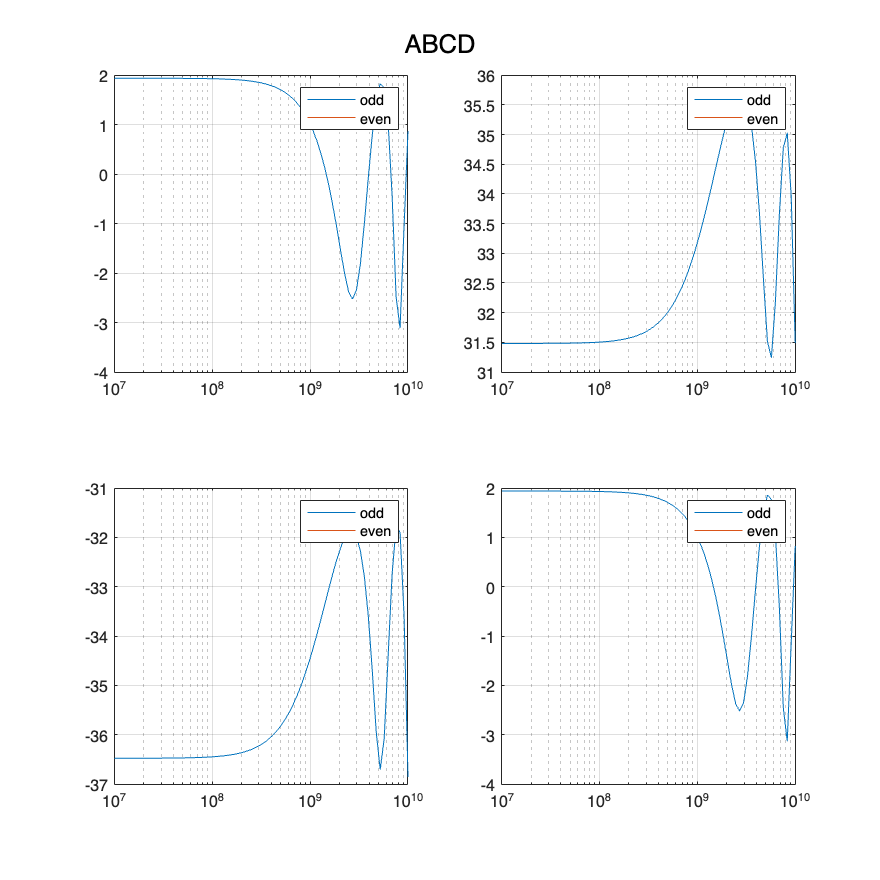

% Convert S_odd and S_even to ABCD matrices
ABCD_odd = zeros(2, 2, fpoints);
ABCD_even = zeros(2, 2, fpoints);

for k = 1:fpoints
    ABCD_odd(:, :, k) = s2abcd(S_odd(:, :, k));
    ABCD_even(:, :, k) = s2abcd(S_even(:, :, k));
end

plot_full_ABCD_params(f, ABCD_odd, ABCD_even, 'ABCD');

## Parameters

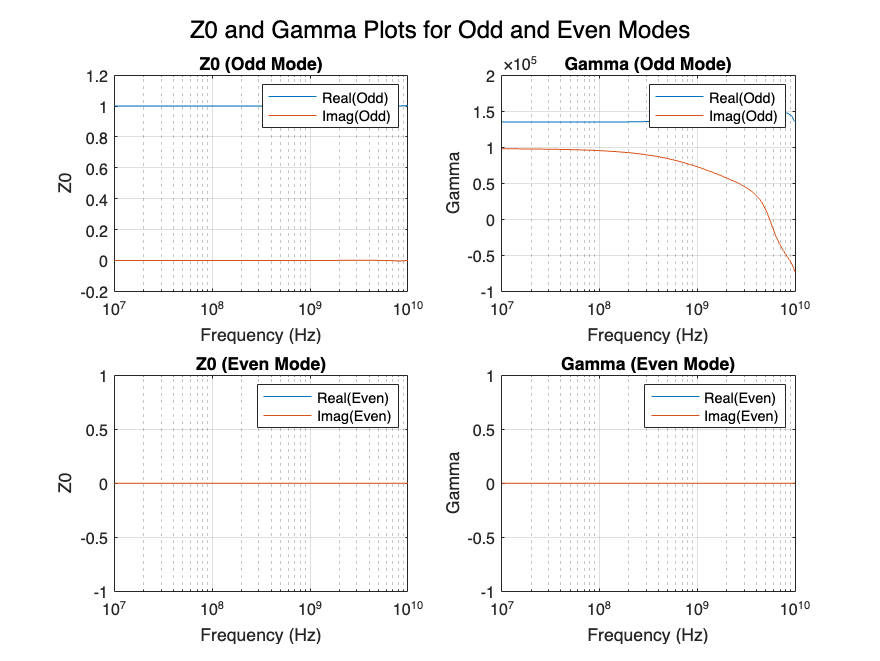

[Z0_odd, gamma_odd] = ABCD2Z0Gamma(f, l*num_of_sections, ABCD_odd);
[Z0_even, gamma_even] = ABCD2Z0Gamma(f, l*num_of_sections, ABCD_even);

plotZ0Gamma(f, Z0_odd, Z0_even, gamma_odd, gamma_even);

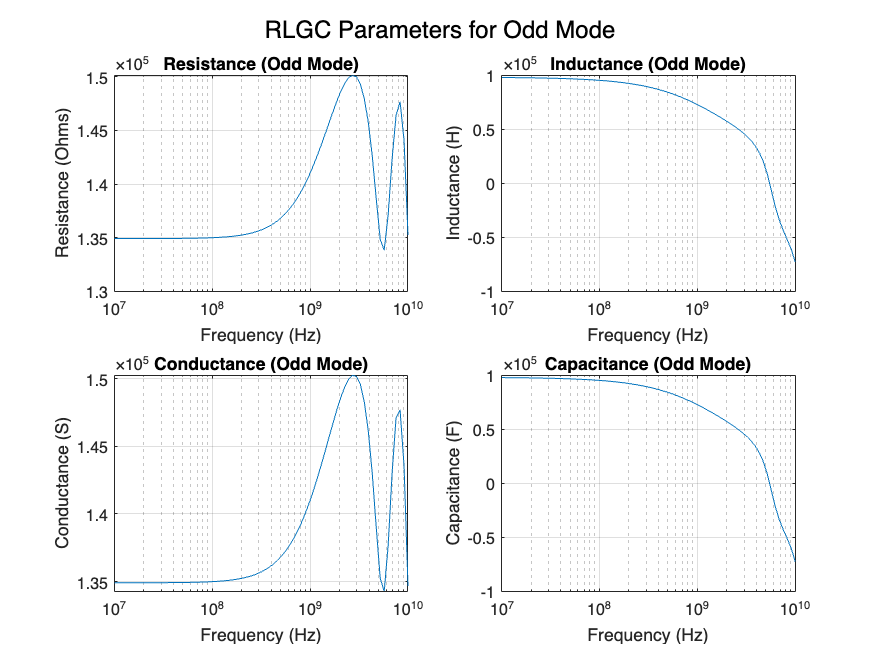

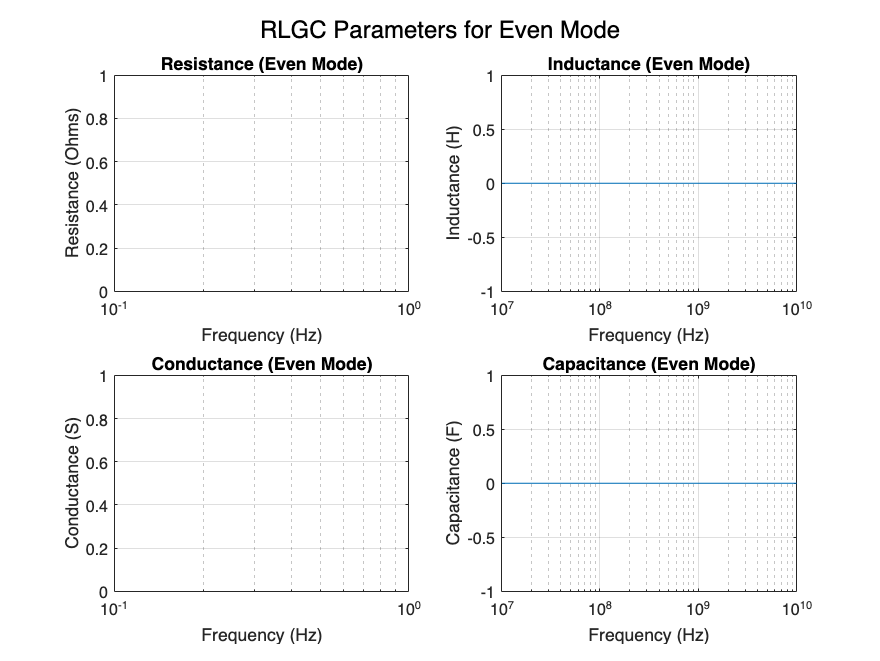


[R_odd, L_odd, G_odd, C_odd] = Z0Gamma2RLGC(Z0_odd, gamma_odd);
[R_even, L_even, G_even, C_even] = Z0Gamma2RLGC(Z0_even, gamma_even);

plotRLGC(f, R_odd, L_odd, G_odd, C_odd, R_even, L_even, G_even, C_even);


C_shunt = 10*max(C_odd);

writeToCSV('RLGCK.csv', f, Z0_odd, gamma_odd, Z0_even, gamma_even, R_odd, L_odd, G_odd, C_odd, R_even, L_even, G_even, C_even);
[f, Z0_odd, gamma_odd, Z0_even, gamma_even, R_odd, L_odd, G_odd, C_odd, R_even, L_even, G_even, C_even] = readFromCSV('RLGCK.csv');

## Extract Parameters

function [Z0, gamma] = ABCD2Z0Gamma(f, l, ABCD)
    A11 = reshape(ABCD(1, 1, :), [1, length(f)]);
    A22 = reshape(ABCD(2, 2, :), [1, length(f)]);
    A12 = reshape(ABCD(1, 2, :), [1, length(f)]);

    Z0 = sqrt(A11./A22);
    gamma = acosh(A12)./l;
end

function [R, L, G, C] = Z0Gamma2RLGC(Z0, gamma)

    R = real(gamma.*Z0);
    L = imag(gamma.*Z0);
    G = real(gamma./Z0);
    C = imag(gamma./Z0);
end

## Plotting

function plot_full_S_params(f, S, title)
    gridSize = ceil(sqrt(16));
    fig_S_params = figure;
    for i = 1:16
        subplot(gridSize, gridSize, i);
        semilogx(f, reshape( 20*log10(abs(S(floor((i-1)/4)+1, mod(i-1, 4)+1, :))) , [1, length(f)] ) );
        grid on;
    end
    sgtitle(title, 'FontSize', 16);
    set(gcf, 'Position', [100, 100, 1000, 1000]);
end

function plot_S_params(f, S, title)

    gridSize = ceil(sqrt(4));
    fig_S_params = figure;
    for i = 1:4
        subplot(gridSize, gridSize, i);
        semilogx(f, reshape( 20*log10(abs(S(floor((i-1)/2)+1, mod(i-1, 2)+1, :))) , [1, length(f)] ));
        grid on;
    end
    sgtitle(title, 'FontSize', 16);
    set(gcf, 'Position', [100, 100, 1000, 1000]);
end

function plot_full_ABCD_params(f, Ao, Ae, title)
    gridSize = ceil(sqrt(4));
    fig_A_params = figure;
    for i = 1:4
        subplot(gridSize, gridSize, i);
        semilogx(f, reshape( 20*log10(abs(Ao(floor((i-1)/2)+1, mod(i-1, 2)+1, :))) , [1, length(f)] ) );
        hold on;
        semilogx(f, reshape( 20*log10(abs(Ae(floor((i-1)/2)+1, mod(i-1, 2)+1, :))) , [1, length(f)] ) );
        grid on;
        legend('odd', 'even');
    end
    sgtitle(title, 'FontSize', 16);
    set(gcf, 'Position', [100, 100, 1000, 1000]);
end

function plotZ0Gamma(f, Z0_odd, Z0_even, gamma_odd, gamma_even)
    
    % Create a 2x2 subplot
    figure;
    
    % Plot Z0 for odd mode
    subplot(2, 2, 1);
    semilogx(f, real(Z0_odd));
    hold on;
    semilogx(f, imag(Z0_odd));
    title('Z0 (Odd Mode)');
    xlabel('Frequency (Hz)');
    ylabel('Z0');
    grid on;
    legend('Real(Odd)', 'Imag(Odd)');

    % Plot gamma for odd mode
    subplot(2, 2, 2);
    semilogx(f, real(gamma_odd));
    hold on;
    semilogx(f, imag(gamma_odd));
    title('Gamma (Odd Mode)');
    xlabel('Frequency (Hz)');
    ylabel('Gamma');
    grid on;
    legend('Real(Odd)', 'Imag(Odd)');

    % Plot Z0 for even mode
    subplot(2, 2, 3);
    semilogx(f, real(Z0_even));
    hold on;
    semilogx(f, imag(Z0_even));
    title('Z0 (Even Mode)');
    xlabel('Frequency (Hz)');
    ylabel('Z0');
    grid on;
    legend('Real(Even)', 'Imag(Even)');

    % Plot gamma for even mode
    subplot(2, 2, 4);
    semilogx(f, real(gamma_even));
    hold on;
    semilogx(f, imag(gamma_even));
    title('Gamma (Even Mode)');
    xlabel('Frequency (Hz)');
    ylabel('Gamma');
    grid on;
    legend('Real(Even)', 'Imag(Even)');

    % Adjust subplot layout
    sgtitle('Z0 and Gamma Plots for Odd and Even Modes');
end

function plotRLGC(f, R_odd, L_odd, G_odd, C_odd, R_even, L_even, G_even, C_even)
    
    % Create a 2x2 subplot with two axes in each subplot
    figure;
    
    % Plot RLGC parameters for odd mode
    subplot(2, 2, 1);
    
    % Plot Resistance (R) for odd mode
    ax1 = subplot(2, 2, 1);
    semilogx(ax1, f, R_odd);
    title(ax1, 'Resistance (Odd Mode)');
    xlabel(ax1, 'Frequency (Hz)');
    ylabel(ax1, 'Resistance (Ohms)');
    grid on;

    % Plot Inductance (L) for odd mode
    ax2 = subplot(2, 2, 2);
    semilogx(ax2, f, L_odd);
    title(ax2, 'Inductance (Odd Mode)');
    xlabel(ax2, 'Frequency (Hz)');
    ylabel(ax2, 'Inductance (H)');
    grid on;

    % Plot Conductance (G) for odd mode
    ax3 = subplot(2, 2, 3);
    semilogx(ax3, f, G_odd);
    title(ax3, 'Conductance (Odd Mode)');
    xlabel(ax3, 'Frequency (Hz)');
    ylabel(ax3, 'Conductance (S)');
    grid on;

    % Plot Capacitance (C) for odd mode
    ax4 = subplot(2, 2, 4);
    semilogx(ax4, f, C_odd);
    title(ax4, 'Capacitance (Odd Mode)');
    xlabel(ax4, 'Frequency (Hz)');
    ylabel(ax4, 'Capacitance (F)');
    grid on;
    
    % Adjust subplot layout
    sgtitle('RLGC Parameters for Odd Mode');
    
    % Create a new figure for even mode
    figure;
    
    % Plot RLGC parameters for even mode
    subplot(2, 2, 1);
    
    % Plot Resistance (R) for even mode
    ax1 = subplot(2, 2, 1);
    semilogx(ax1, f, R_even);
    title(ax1, 'Resistance (Even Mode)');
    xlabel(ax1, 'Frequency (Hz)');
    ylabel(ax1, 'Resistance (Ohms)');
    grid on;

    % Plot Inductance (L) for even mode
    ax2 = subplot(2, 2, 2);
    semilogx(ax2, f, L_even);
    title(ax2, 'Inductance (Even Mode)');
    xlabel(ax2, 'Frequency (Hz)');
    ylabel(ax2, 'Inductance (H)');
    grid on;

    % Plot Conductance (G) for even mode
    ax3 = subplot(2, 2, 3);
    semilogx(ax3, f, G_even);
    title(ax3, 'Conductance (Even Mode)');
    xlabel(ax3, 'Frequency (Hz)');
    ylabel(ax3, 'Conductance (S)');
    grid on;

    % Plot Capacitance (C) for even mode
    ax4 = subplot(2, 2, 4);
    semilogx(ax4, f, C_even);
    title(ax4, 'Capacitance (Even Mode)');
    xlabel(ax4, 'Frequency (Hz)');
    ylabel(ax4, 'Capacitance (F)');
    grid on;
    
    % Adjust subplot layout
    sgtitle('RLGC Parameters for Even Mode');
end


function writeToCSV(filename, f, Z0_odd, gamma_odd, Z0_even, gamma_even, R_odd, L_odd, G_odd, C_odd, R_even, L_even, G_even, C_even)
    % Create a matrix with all the data
    dataMatrix = [f; Z0_odd; gamma_odd; Z0_even; gamma_even; R_odd; L_odd; G_odd; C_odd; R_even; L_even; G_even; C_even];

    % Write the matrix to a CSV file
    writematrix(dataMatrix', filename);
end

function [f, Z0_odd, gamma_odd, Z0_even, gamma_even, R_odd, L_odd, G_odd, C_odd, R_even, L_even, G_even, C_even] = readFromCSV(filename)
    % Read the matrix from the CSV file
    dataMatrix = readmatrix(filename);

    % Extract the arrays from the matrix
    f = dataMatrix(:, 1);
    Z0_odd = dataMatrix(:, 2);
    gamma_odd = dataMatrix(:, 3);
    Z0_even = dataMatrix(:, 4);
    gamma_even = dataMatrix(:, 5);
    R_odd = dataMatrix(:, 6);
    L_odd = dataMatrix(:, 7);
    G_odd = dataMatrix(:, 8);
    C_odd = dataMatrix(:, 9);
    R_even = dataMatrix(:, 10);
    L_even = dataMatrix(:, 11);
    G_even = dataMatrix(:, 12);
    C_even = dataMatrix(:, 13);
end

